## Newton Rapson Load Flow for 3-bus system

clc;
clear;

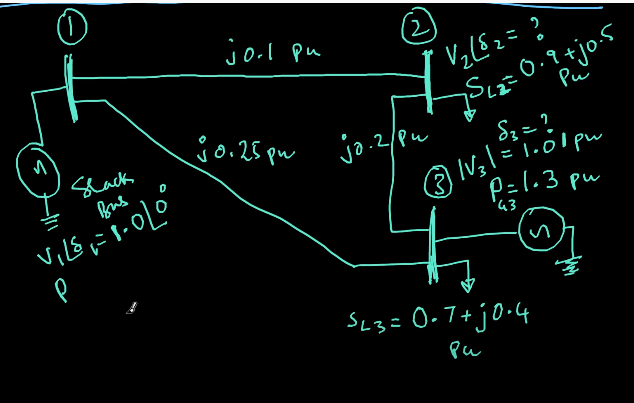

Defining the Ybus elements (Admittance Matrix)

Y11 = 14; Y21 = 10; Y31 = 4;
Y21 = 10; Y22 = 15; Y23 = 5;
Y31 = 4 ; Y32 = 5 ; Y33 = 9;


Theta matrix

t11 = pi/2; t12 = -pi/2; t13 =- pi/2;
t21 = -pi/2; t22 = pi/2; t23 = -pi/2;
t31 = -pi/2; t32 = -pi/2; t33 = pi/2;

Defining the know states

d1 = 0; v1 = 1.0; v3 = 1.01;

Defining the power injections

p2 = -0.9;  q2 = -0.5;
p3 = 1.3 - 0.7; 

Defining the initial values of unknown

d2 = 0; d3 = 0; v2 = 1.0;
X = [d2; d3; v2];
disp(X')

     0     0     1



% fp2 =  Y21*v1*v2*cos(t21+d1-d2) + Y22*v2^2*cos(t22) + Y23*v2*v3*cos(t23 + d3 - d2) - p2;
% fp3 =  Y31*v1*v3*sin(t31+d1-d3) + Y32*v3*v2*cos(t32 + d2 - d3) + Y33 * v3^2 * cos(t33) - p3;
% fq2 = -Y21*v1*v2*sin(t21+d1-d2) - Y22*v2^2*sin(t22) - Y23*v3*v2*sin(t23 + d3 - d2) - q2;


Jacobian Matrix

% syms d1 d2 d3 v1 v2 v3 t11 t12 t13 t21 t22 t23 t31 t32 t33 Y11 Y12 Y13 Y21 Y22 Y23 Y31 Y32 Y33
% 
% jacobian([ Y21*v1*v2*cos(t21+d1-d2) + Y22*v2^2*cos(t22) + Y23*v2*v3*cos(t23 + d3 - d2) - p2 , ...
%          Y31*v1*v3*sin(t31+d1-d3) + Y32*v3*v2*cos(t32 + d2 - d3) + Y33 * v3^2 * cos(t33) - p3,...
%          -Y21*v1*v2*sin(t21+d1-d2) - Y22*v2^2*sin(t22) - Y23*v3*v2*sin(t23 + d3 - d2) - q2], ...
%          [d2; d3; v2])
%      

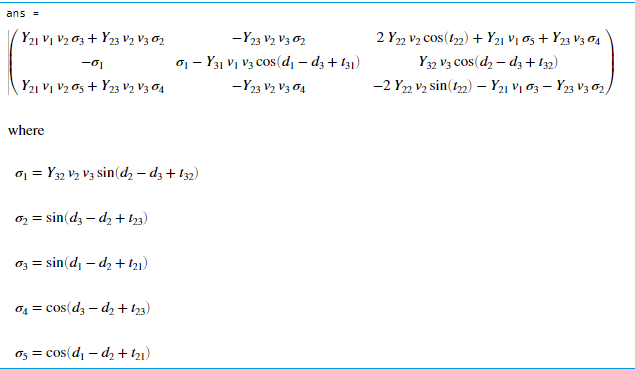

Note sin ( rad.) as normal

sin 45deg = sin (deg2rad(45))

X = X - J \fx :

X = X - inverse(J)  fx

% clear d1 d2 d3 v1 v2 v3 t11 t12 t13 t21 t22 t23 t31 t32 t33 Y11 Y12 Y13 Y21 Y22 Y23 Y31 Y32 Y33

for m = 1 : 10
    
    fp2 =  Y21*v1*v2*cos(t21+d1-d2) + Y22*v2^2*cos(t22) + Y23*v2*v3*cos(t23 + d3 - d2) - p2;
    fp3 =  Y31*v1*v3*sin(t31+d1-d3) + Y32*v3*v2*cos(t32 + d2 - d3) + Y33 * v3^2 * cos(t33) - p3;
    fq2 = -Y21*v1*v2*sin(t21+d1-d2) - Y22*v2^2*sin(t22) - Y23*v3*v2*sin(t23 + d3 - d2) - q2;
%     
    fx = [fp2; fp3; fq2];
    
    J11 =   Y21*v1*v2*sin(t21+d1-d2) + Y23*v3*v2*sin(t23+d3-d2) ;
    J12 = - Y23*v3*v2*sin(t23+d3-d2);
    J13 =   Y21*v1*cos(t21+d1-d2) + 2*Y22*v2*cos(t22) + Y23*v3*cos(t23+d3-d2) ;
    
    J21 = -Y32*v2*v3*sin(t32+d2-d3);
    J22 = -Y31*v1*v3*sin(t31+d1-d3) + Y32*v2*v3*sin(t32+d2-d3);
    J23 =  Y32*v3*cos(t32 +d2-d3);
%     
    J31 = Y21*v1*v2*cos(t21+d1-d2) +Y23*v3*v2*cos(t23+d3-d2);
    J32 = -Y23*v3*v2*cos(t23 + d3 - d2);
    J33 = -Y21*v1*sin(t21 + d1 -d2) -2*Y22*v2*sin(t22) -Y23*v3*sin(t23+d3-d2);


    J = [J11 J12 J12; J21 J22 J23; J31 J32 J33];
    
    X = X - J \fx; %iteration - calculation of collection
    
    disp(X')
end

    2.1681    6.2462    1.0368

    4.3361   12.4925    1.0736

    6.5042   18.7387    1.1104

    8.6722   24.9850    1.1472

   10.8403   31.2312    1.1839

   13.0084   37.4774    1.2207

   15.1764   43.7237    1.2575

   17.3445   49.9699    1.2943

   19.5125   56.2162    1.3311

   21.6806   62.4624    1.3679




disp('v2')

v2


X(3)

ans = 1.3679

disp('Delta2')

Delta2


X(1) * 180 / pi

ans = 1.2422e+03

disp('Delta3')

Delta3


X(2) *180 / pi

ans = 3.5788e+03

Using MATLAB Jacobian

% syms d1 d2 d3 v1 v2 v3 t11 t12 t13 t21 t22 t23 t31 t32 t33 Y11 Y12 Y13 Y21 Y22 Y23 Y31 Y32 Y33
% J_2 = jacobian([ ...
%     Y21*v1*v2*cos(t21+d1-d2) + Y22*v2^2*cos(t22) + Y23*v2*v3*cos(t23 + d3 - d2) - p2 , ...
%     Y31*v1*v3*sin(t31+d1-d3) + Y32*v3*v2*cos(t32 + d2 - d3) + Y33 * v3^2 * cos(t33) - p3,...
%     -Y21*v1*v2*sin(t21+d1-d2) - Y22*v2^2*sin(t22) - Y23*v3*v2*sin(t23 + d3 - d2) - q2 ...
%     ],[d2; d3; v2])
     